# Team 3: Hexapod Robot Rigid Body Tree Joint Space Motion Model

#### Gary Encinas, Justin Fossum, Jason Munger, and Mithulesh Ramkumar

## Building The Model

This code was derived and adjusted from our group script called "Hexapod_Robot_Max_Joint_Angle_Model.mlx" in which we built leg six of the hexapod robot in the rigid body model.

### Environment Setup

First, we should remove items from workspace, freeing up system memory, and clear current command window.

close all; % Close all current figure windows
clear; % Remove items from workspace, freeing up system memory
clc; % Clear current command window

print_figures = false;

### Building the Rigid Tree Model

When building this model, the leg length visual meshes are reused, so rather than the full string path every time, we have listed them all as variables in the beginning. Keeping true with that fashion, the DH parameters are only changed by a ratio of $\frac{\pi }{3}$ each new leg so there is a count variable that can be called to index the leg creations.

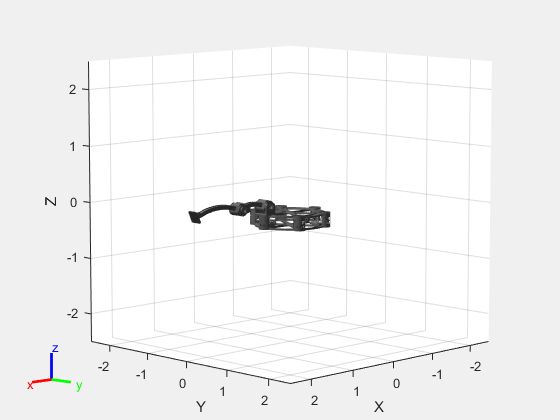

body_mesh = "..\Robot CAD\STL\Body_Link.STL";
link1_vmesh = "..\Robot CAD\STL\Link_One_L2Out.STL";
link2_vmesh = "..\Robot CAD\STL\Link_Two_640_L3Out.STL";
link3_vmesh = "..\Robot CAD\STL\Link_Three_960_EEOut_MovedFoot_700.STL";

count = 6; % Counting variable for itterating through the legs with the order being 2, 1, 3, 5, 6, 4 for leg names.

a = [0.625 0 0.640 0.960]; % Link lengths as a 1:1.5 leg ratio.
alpha = [0 pi/2 0 -pi/2];
d = [0 0 0 0];
theta = [pi/3*count 0 0 0];
DHparams = [a(1)      alpha(1)      d(1)   theta(1);
            a(2)      alpha(2)      d(2)   theta(2);
            a(3)      alpha(3)      d(3)   theta(3);
            a(4)      alpha(4)      d(4)   theta(4)];

%Building The Robot by creating a rigid body tree
leg_four_model = robotics.RigidBodyTree; %Sets rigid body tree to be called robot for callback use

% Define the bodies and their joints
leg_4 = robotics.RigidBody('leg_4'); %Create Leg 6 Origin of the robot.
leg4_jnt1 = robotics.Joint('leg4_jnt1','fixed'); %Create a fixed joint.
leg4_link1 = robotics.RigidBody('leg4_link1'); %Create Link 1 of the leg 6.
leg4_jnt2 = robotics.Joint('leg4_jnt2','revolute'); %Create a revolute joint.
leg4_link2 = robotics.RigidBody('leg4_link2'); %Create Link 2 of the leg 6.
leg4_jnt3 = robotics.Joint('leg4_jnt3','revolute'); %Create a revolute joint.
leg4_link3 = robotics.RigidBody('leg4_link3'); %Create Link 3 of the leg 6.
leg4_jnt4 = robotics.Joint('leg4_jnt4','revolute'); %Create a revolute joint.

% Specify the body-to-body transformation using DH parameters
setFixedTransform(leg4_jnt1,DHparams(1,:),'dh');
setFixedTransform(leg4_jnt2,DHparams(2,:),'dh');
setFixedTransform(leg4_jnt3,DHparams(3,:),'dh');
setFixedTransform(leg4_jnt4,DHparams(4,:),'dh');

% Specify the body joints
leg_4.Joint = leg4_jnt1;
leg4_link1.Joint = leg4_jnt2;
leg4_link2.Joint = leg4_jnt3;
leg4_link3.Joint = leg4_jnt4;

% Specify the body mass
leg4_link1.Mass = 26.6416;
leg4_link2.Mass = 39.1890;
leg4_link3.Mass = 23.2205;

leg4_link1.CenterOfMass = [-0.0001, -0.0242, 0.0061];
leg4_link2.CenterOfMass = [-0.3006, 0.0052, 0.0003];
leg4_link3.CenterOfMass = [-0.7799, 0.0040, 0.0081];

% Add the STL visual to the body
addVisual(leg_4, "Mesh", body_mesh);

% Add the STL visual to the first link
addVisual(leg4_link1, "Mesh", link1_vmesh);

% Add the STL visual to the second link
addVisual(leg4_link2, "Mesh", link2_vmesh);

% Add the STL visual to the third link
addVisual(leg4_link3, "Mesh", link3_vmesh);

% Attach the sixth Leg
addBody(leg_four_model,leg_4,'base')
addBody(leg_four_model,leg4_link1,'leg_4');
addBody(leg_four_model,leg4_link2,'leg4_link1');
addBody(leg_four_model,leg4_link3,'leg4_link2');

config = homeConfiguration(leg_four_model);
figure('Name','Initial Robot State')
show(leg_four_model,config,"Frames","off");

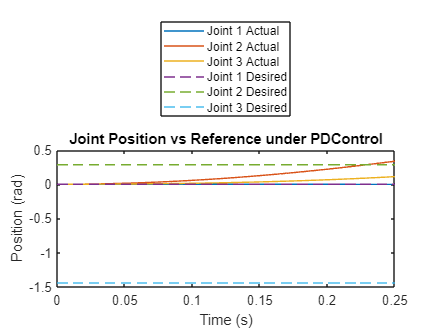


leg_four_model.DataFormat = 'row';
leg_four_model.Gravity = [0 0 -9.81];

% Define the timespan and initial and target robot states
tspan = 0:0.005:0.25;
initial_state = [0,0,0,0,0,0];
% [0,16.256,-82.575] Robot joint angles in degrees when standing at 700mm

% PD Control
target_state = [0,deg2rad(16.256),deg2rad(-82.575),0,0,0];
motion_model = jointSpaceMotionModel("RigidBodyTree",leg_four_model,"MotionType","PDControl");
desired_response_time = 0.025; % Response time of .025 seconds
desired_overshoot = 0.02; % Overshoot of 2%
updateErrorDynamicsFromStep(motion_model,desired_response_time,desired_overshoot); 

[t,robot_state] = ode45(@(t,state)derivative(motion_model,state,target_state),tspan,initial_state);

figure('Name','Joint Position vs Reference')
plot(t,robot_state(:,1:motion_model.NumJoints));
hold on;
plot(t,target_state(1:motion_model.NumJoints).*ones(length(t),1),"--");
hold off;
title_name = 'Joint Position vs Reference under ' + string(motion_model.MotionType);
title(title_name);
xlabel("Time (s)")
ylabel("Position (rad)");
legend('Joint 1 Actual','Joint 2 Actual','Joint 3 Actual','Joint 1 Desired','Joint 2 Desired','Joint 3 Desired',Location='northoutside')

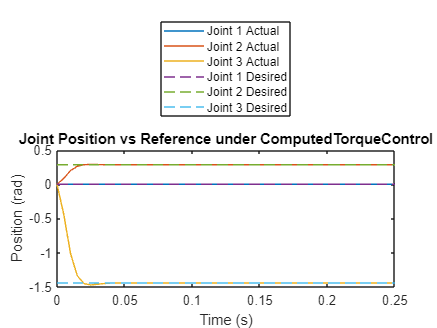


if print_figures
    figure_name = 'Single Leg Step Response with Response Time of ' + string(desired_response_time) + 'and Overshoot of ' +string(desired_overshoot)
    set(gcf,'Units','inches'); % Set the units of the figure
    screenposition = get(gcf,'Position'); % Measure the size of the figure
    set(gcf,'PaperPosition', [0 0 screenposition(3:4)],'PaperSize' , (screenposition(3:4))); % Configures the print paper size to fit the figure size
    print(figure_name, '-dpng', '-r600') % Save figure as PNG
end

% Computed Torque Control
target_state = [0,deg2rad(16.256),deg2rad(-82.575),0,0,0,0,0,0];
motion_model = jointSpaceMotionModel("RigidBodyTree",leg_four_model,"MotionType","ComputedTorqueControl");
desired_response_time = 0.025; % Response time of .025 seconds
desired_overshoot = 0.02; % Overshoot of 2%
updateErrorDynamicsFromStep(motion_model,desired_response_time,desired_overshoot); 

[t,robot_state] = ode45(@(t,state)derivative(motion_model,state,target_state),tspan,initial_state);

figure('Name','Joint Position vs Reference')
plot(t,robot_state(:,1:motion_model.NumJoints));
hold on;
plot(t,target_state(1:motion_model.NumJoints).*ones(length(t),1),"--");
hold off;
title_name = 'Joint Position vs Reference under ' + string(motion_model.MotionType);
title(title_name);
xlabel("Time (s)")
ylabel("Position (rad)");
legend('Joint 1 Actual','Joint 2 Actual','Joint 3 Actual','Joint 1 Desired','Joint 2 Desired','Joint 3 Desired',Location='northoutside')

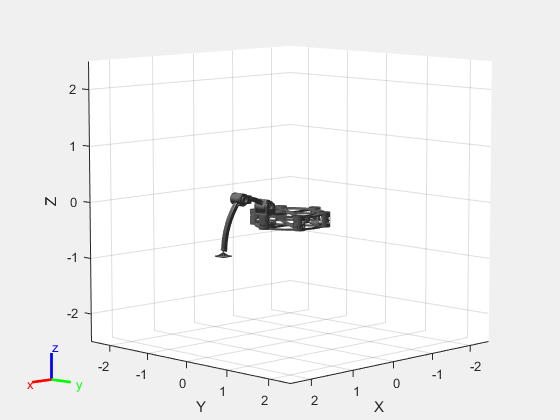


if print_figures
    figure_name = 'Single Leg Step Response with Response Time of ' + string(desired_response_time) + 'and Overshoot of ' +string(desired_overshoot)
    set(gcf,'Units','inches'); % Set the units of the figure
    screenposition = get(gcf,'Position'); % Measure the size of the figure
    set(gcf,'PaperPosition', [0 0 screenposition(3:4)],'PaperSize' , (screenposition(3:4))); % Configures the print paper size to fit the figure size
    print(figure_name, '-dpng', '-r600') % Save figure as PNG
end

figure('Name','Target Robot State')
show(leg_four_model,[0,deg2rad(16.256),deg2rad(-82.575)],"Frames","off");